disp('Metoda bisekcji')

Metoda bisekcji



% funkcja
f = @(x) 2 * exp(-((x/3-1).^2)).^2 + 5*sqrt(x) - 8;

% Funkcja bisekcji
function [tableResults, errors, num_iter] = bisection(f, x_span, delta, x_ref)
    x_min = x_span(1);
    x_max = x_span(2);
    i = 0;
    iter = [];
    errors = [];

    while (x_max - x_min) / 2 > delta
        i = i + 1;  
        x_average = (x_min + x_max) / 2;
        iter = [iter; i, x_average, f(x_average)];

        if sign(f(x_average)) == sign(f(x_min))
            x_min = x_average;
        else
            x_max = x_average;
        end
    end

    x_final = (x_min + x_max) / 2;
    iter = [iter; i+1, x_final, f(x_final)];
    errors = abs(iter(:, 2) - x_ref);  % Błąd bezwzględny względem x_ref
    tableResults = array2table(iter, 'VariableNames', {'Iteration', 'x', 'f(x)'});
    num_iter = i + 1;
end

% Obliczenie miejsca zerowego za pomocą fzero jako punkt odniesienia
x_span = [1, 10];
x_ref = fzero(f, x_span);  % <- Punkt odniesienia
disp(['Miejsce zerowe obliczone za pomocą fzero: ', num2str(x_ref)]);

Miejsce zerowe obliczone za pomocą fzero: 1.7397



% Przykład użycia funkcji bisection i wyświetlenie wyników
delta = 10^-10; % Przykładowa wartość delta

[tableResults_bisection, errors_bisection, num_iter_bisection] = bisection(f, x_span, delta, x_ref);  % <- Wywołanie z x_ref
disp(tableResults_bisection);

    Iteration      x          f(x)    
    _________    ______    ___________

        1           5.5         4.2247
        2          3.25         2.9863
        3         2.125        0.97579
        4        1.5625       -0.48642
        5        1.8438        0.27519
        6        1.7031      -0.098514
        7        1.7734       0.090168
        8        1.7383     -0.0037228
        9        1.7559       0.043336
       10        1.7471       0.019835
       11        1.7427       0.008063
       12        1.7405      0.0021719
       13        1.7394    -0.00077505
       14        1.7399     0.00069851
       15        1.7397    -3.8239e-05
       16        1.7398     0.00033014
       17        1.7397     0.00014595
       18        1.7397     5.3858e-05
       19        1.7397     7.8093e-06
       20        1.7397    -1.5215e-05
       21        1.7397    -3.7028e-06



disp('Metoda siecznych')

Metoda siecznych



% Funkcja metody siecznych
function [tableResults, errors, num_iter] = secant_method(f, x_span, delta, x_ref)
    x_prev = x_span(1);
    x_curr = x_span(2);
    k = 1;
    iter_data = [];

    % Warunek while: abs(x_curr - x_ref) >= delta
    while abs(x_curr - x_ref) >= delta
        x_next = x_curr - ((x_curr - x_prev) / (f(x_curr) - f(x_prev))) * f(x_curr);
        modulus_f = abs(f(x_next));
        modulus_x = abs(x_next - x_ref);  % Zmiana warunku zatrzymania na różnicę między x_next a x_ref
        f_val = f(x_next);
        iter_data = [iter_data; k, x_next, f_val, modulus_f, modulus_x];
        
        if abs(x_next - x_ref) < delta
            break;
        end
        
        x_prev = x_curr;
        x_curr = x_next;
        k = k + 1;
    end

    tableResults = array2table(iter_data, 'VariableNames', {'Iteration', 'x', 'f(x)', 'f(x)_modulus', 'x_modulus'});
    errors = abs(iter_data(:, 2) - x_ref);  % Błąd bezwzględny względem x_ref
    num_iter = k;
end

% Przykład użycia funkcji secant_method i wyświetlenie wyników
delta = 10^-10; % Przykładowa wartość delta

[tableResults_secant, errors_secant, num_iter_secant] = secant_method(f, x_span, delta, x_ref);  % <- Wywołanie z x_ref
disp(tableResults_secant);

    Iteration             x                       f(x)             f(x)_modulus    x_modulus 
    _________    ____________________    ______________________    ____________    __________

        1          2.9621+0i                 2.6048+0i                  2.6048         1.2224
        2        -0.55876+0i                -7.8801+3.7375i             8.7215         2.2984
        3           2.186-0.27665i           1.1544-0.64227i             1.321        0.52515
        4          1.8275-0.21997i          0.25115-0.57643i           0.62876        0.23687
        5          1.7466+0.018691i        0.018696+0.050044i         0.053422       0.019933
        6           1.739+2.4807e-05i    -0.0017596+6.6558e-05i      0.0017609     0.00065637
        7          1.7397+1.6476e-06i    1.8032e-06+4.4198e-06i     4.7735e-0


disp('Metoda Newtona')

Metoda Newtona



% Funkcja metody Newtona
function [tableResults, errors, num_iter] = newton_method(f, x_start, delta, x_ref)
    x_curr = x_start;
    f_prime = @(x) (f(x + 1e-10) - f(x - 1e-10)) / (2 * 10^-10);
    k = 1;
    iter_data = [];

    % Warunek while: abs(x_curr - x_ref) >= delta
    while abs(x_curr - x_ref) >= delta
        x_next = x_curr - f(x_curr) / f_prime(x_curr);
        f_val = f(x_next);
        iter_data = [iter_data; k, x_next, f_val];
        
        if abs(x_next - x_ref) < delta
            break;
        end
        
        x_curr = x_next;
        k = k + 1;
    end

    tableResults = array2table(iter_data, 'VariableNames', {'Iteration', 'x', 'f(x)'});
    errors = abs(iter_data(:, 2) - x_ref); % Błąd bezwzględny względem x_ref
    num_iter = k;
end

% Wywołanie funkcji newton_method i wyświetlenie wyników
[tableResults_newton1, errors_newton1, num_iter_newton1] = newton_method(f, x_span(1), delta, x_ref);
disp('Wyniki dla x_start = x_min');

Wyniki dla x_start = x_min


disp(tableResults_newton1);

    Iteration      x          f(x)    
    _________    ______    ___________

        1        1.6741       -0.17757
        2        1.7391     -0.0015124
        3        1.7397    -1.1931e-07
        4        1.7397     2.1316e-14




[tableResults_newton2, errors_newton2, num_iter_newton2] = newton_method(f, x_span(2), delta, x_ref);
disp('Wyniki dla x_start = x_max');

Wyniki dla x_start = x_max


disp(tableResults_newton2);

    Iteration       x          f(x)    
    _________    _______    ___________

        1        0.11789        -5.9675
        2        0.89432        -2.5249
        3         1.6498        -0.2441
        4         1.7386     -0.0028048
        5         1.7397    -4.0459e-07
        6         1.7397    -5.9064e-13




disp('Metoda Mullera')

Metoda Mullera



% Funkcja metody Mullera
function [tableResults, errors_abs, num_iter] = muller_method(f, x_span, delta, x_ref)
    x1 = x_span(1);
    x2 = x_span(2);
    x3 = (x_span(1) + x_span(2)) / 2;
    k = 1;
    iter_data = [];

    % Warunek while: abs(x3 - x_ref) >= delta
    while abs(x3 - x_ref) >= delta
        % Obliczanie współczynników a i b
        A = [
            -(x3 - x2)^2, (x3 - x2);
            -(x3 - x1)^2, (x3 - x1)
        ];
        B = [
            f(x3) - f(x2);
            f(x3) - f(x1)
        ];
        coeff = A \ B;
        a = coeff(1);
        b = coeff(2);
        c = f(x3);

        % Wybór mianownika
        rad = sqrt(b^2 - 4*a*c);
        denom1 = b + rad;
        denom2 = b - rad;

        if abs(denom1) > abs(denom2)
            denom = denom1;
        else
            denom = denom2;
        end

        % Obliczanie następnego przybliżenia
        x_next = x3 - 2*c / denom;

        % Zapisanie iteracji
        iter_data = [iter_data; k, x_next, f(x_next)];
        
        if abs(x_next - x_ref) < delta
            break;
        end

        x1 = x2;
        x2 = x3;
        x3 = x_next;
        k = k + 1;
    end

    % Tworzenie tabeli wyników
    tableResults = array2table(iter_data, 'VariableNames', {'Iteration', 'x', 'f(x)'});
    errors_abs = abs(iter_data(:, 2) - x_ref); % Błąd bezwzględny względem x_ref
    num_iter = k;
end

% Wywołanie funkcji muller_method i wyświetlenie wyników
[tableResults_muller, errors_abs_muller, num_iter_muller] = muller_method(f, x_span, delta, x_ref);
disp(tableResults_muller);

    Iteration       x          f(x)    
    _________    _______    ___________

        1         2.3251         1.4315
        2        0.78674        -2.8917
        3         1.7341       -0.01499
        4         1.7397      7.176e-05
        5         1.7397    -8.2413e-10
        6         1.7397              0



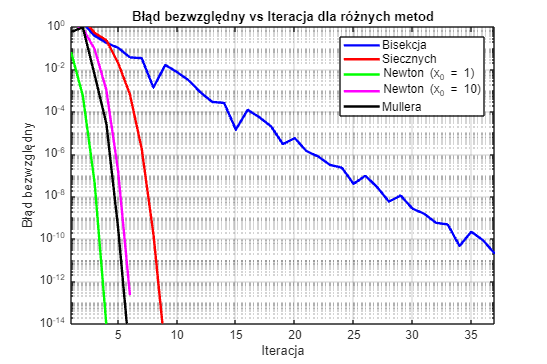


% Rysowanie wspólnego wykresu błędów bezwzględnych dla wszystkich metod
figure('Position', [100, 100, 1200, 800]); % Powiększanie wykresu
semilogy(1:length(errors_bisection), errors_bisection, 'b-', 'LineWidth', 2);
hold on;
semilogy(1:length(errors_secant), errors_secant, 'r-', 'LineWidth', 2);
semilogy(1:length(errors_newton1), errors_newton1, 'g-', 'LineWidth', 2);
semilogy(1:length(errors_newton2), errors_newton2, 'm-', 'LineWidth', 2);
semilogy(1:length(errors_abs_muller), errors_abs_muller, 'k-', 'LineWidth', 2);
xlabel('Iteracja');
ylabel('Błąd bezwzględny');
title('Błąd bezwzględny vs Iteracja dla różnych metod');
legend_handle = legend('Bisekcja', 'Siecznych', 'Newton (x_0 = 1)', 'Newton (x_0 = 10)', 'Mullera');
grid on;
xlim([1, max([length(errors_bisection), length(errors_secant), length(errors_newton1), length(errors_newton2), length(errors_abs_muller)])]); % Ustawienie zakresu osi X
ylim([10^-14, 1]); % Ustawienie zakresu osi Y
hold off;
set(legend_handle, 'FontSize', 10); % Ustawienie rozmiaru czcionki legendy

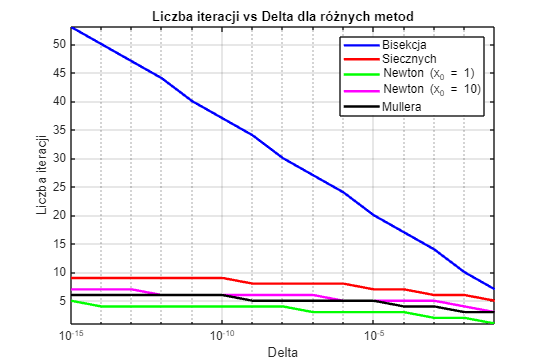


% Zakres wartości delta
deltas = logspace(-15, -1, 15);

% Wyznaczenie liczby iteracji dla różnych wartości delta dla każdej metody
num_iterations_bisection = zeros(length(deltas), 1);
num_iterations_secant = zeros(length(deltas), 1);
num_iterations_newton_start1 = zeros(length(deltas), 1);
num_iterations_newton_start2 = zeros(length(deltas), 1);
num_iterations_muller = zeros(length(deltas), 1);

for j = 1:length(deltas)
    epsilon = deltas(j);
    [~, ~, num_iter_bis] = bisection(f, x_span, epsilon, x_ref);
    num_iterations_bisection(j) = num_iter_bis;
    [~, ~, num_iter_sec] = secant_method(f, [1, 10], epsilon, x_ref);
    num_iterations_secant(j) = num_iter_sec;
    [~, ~, num_iter_new1] = newton_method(f, x_span(1), epsilon, x_ref);
    num_iterations_newton_start1(j) = num_iter_new1;
    [~, ~, num_iter_new2] = newton_method(f, x_span(2), epsilon, x_ref);
    num_iterations_newton_start2(j) = num_iter_new2;
    [~, ~, num_iter_mull] = muller_method(f, x_span, epsilon, x_ref);
    num_iterations_muller(j) = num_iter_mull;
end

% Rysowanie wspólnego wykresu liczby iteracji w zależności od delta dla wszystkich metod
figure('Position', [100, 100, 1200, 800]); % Powiększanie wykresu
plot(deltas, num_iterations_bisection, 'b-', 'LineWidth', 2);
hold on;
plot(deltas, num_iterations_secant, 'r-', 'LineWidth', 2);
plot(deltas, num_iterations_newton_start1, 'g-', 'LineWidth', 2);
plot(deltas, num_iterations_newton_start2, 'm-', 'LineWidth', 2);
plot(deltas, num_iterations_muller, 'k-', 'LineWidth', 2);
set(gca, 'XScale', 'log'); % Skala logarytmiczna dla osi X
xlabel('Delta');
ylabel('Liczba iteracji');
title('Liczba iteracji vs Delta dla różnych metod');
legend_handle = legend('Bisekcja', 'Siecznych', 'Newton (x_0 = 1)', 'Newton (x_0 = 10)', 'Mullera');
grid on;
axis tight; % Automatyczne dopasowanie osi
hold off;
set(legend_handle, 'FontSize', 10); % Ustawienie rozmiaru czcionki legendy